## Assignment 7

### Part one

Task 1-2

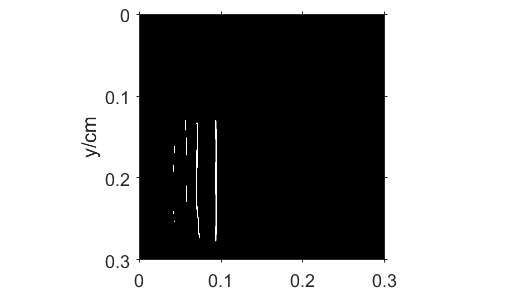

yaxis = linspace(0.3,0,30);
xaxis = linspace(0,0.3,30);
horizontals1 = showImage("hor_lines_bw.bmp",xaxis,yaxis);

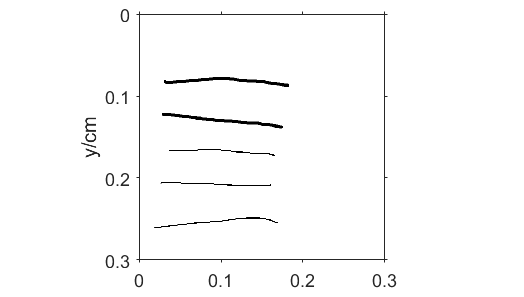

horizontals2 = showImage("hor_lines.bmp",xaxis,yaxis);

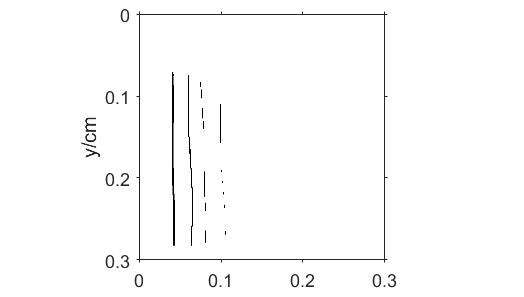

verticals1 = showImage("ver_lines.bmp",xaxis,yaxis);

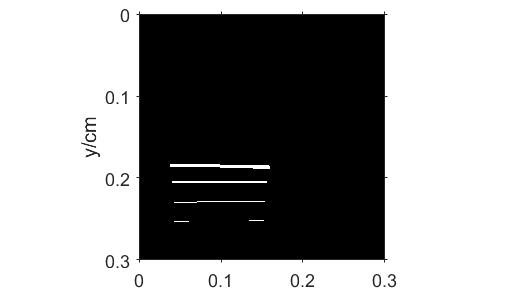

verticals2 = showImage("ver_lines_bw.bmp",xaxis,yaxis);

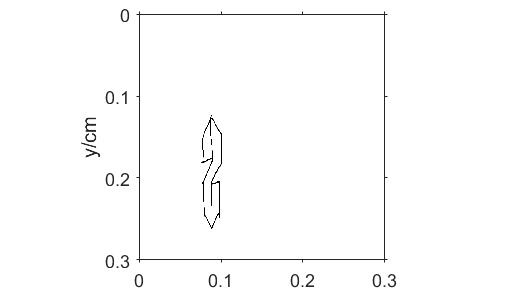

dollasign = showImage("dollasign.bmp",xaxis,yaxis);

Task 3

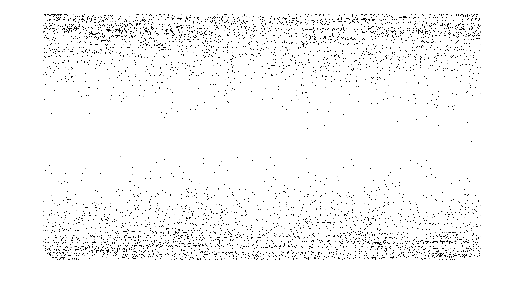

Nfft = 1024;
deltaX = 30;
deltaY = 30;



xfreqs = linspace(-0.5, 0.5, Nfft+1); xfreqs(end) = [];
yfreqs = linspace(-0.5, 0.5, Nfft+1); yfreqs(end) = [];
%figure();
%imshow(20*log10(abs(fft2(horizontals1))));

hor1fft = fft2d(horizontals1);
hor2fft = fft2d(horizontals2);
ver1fft = fft2d(verticals1);
ver2fft = fft2d(verticals2);
 
 
hor1fft_plot = fftimage(hor1fft);

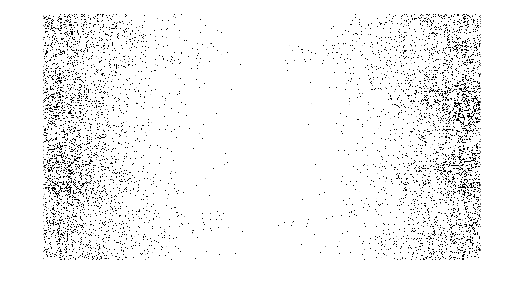

hor2fft_plot = fftimage(hor2fft);

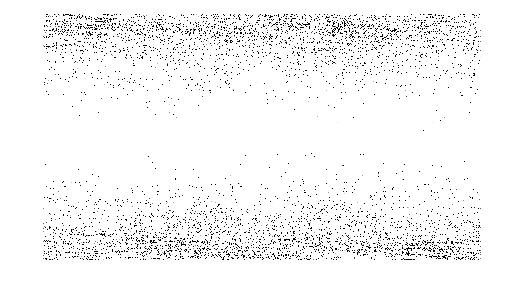

ver1fft_plot = fftimage(ver1fft);

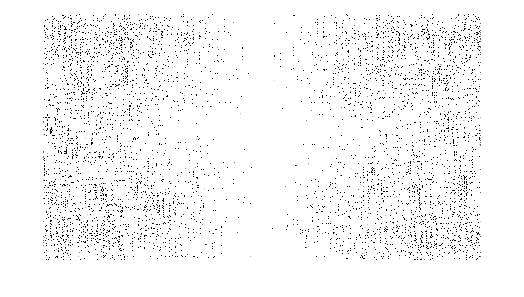

ver2fft_plot = fftimage(ver2fft);

Problem 2

function image = showImage(path,x,y)
    image  = im2double(imread(path));
    figure();
    imshow(image,'XData', x, 'YData', y);
    ylabel('y/cm');
    xlabel('x/cm');
    axis on;
    colormap(gray(255))
end

function res = fft2d(image)
    res = fft2(image);
    res = fftshift(res);
end
function im = fftimage(res)
    figure();
    im = imshow(20*log10(abs(res)));
    dyn = 80;
    gain = -60;
    caxis([-dyn 0]-gain)
    colormap(gray(255));

end
